1.3 Basic functions

disp('Basic functions')

Question 1

disp('Question 1')
pq=[5 9 17 17 5 121; 9 5 9 121 1 1];


fftwave(1,3,128)


Question 2

disp('Question 2')
fftwave(1,3,128)

Question 5

disp('Question 5')
fftwave(1,127,128)

1.4 Linearity

disp('Linearity')

Question 7

disp('Question 7')
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

subplot(1,3,1)
showgrey(F)
title('showgrey(F)')
subplot(1,3,2)
showgrey(G)
title('showgrey(G)')
subplot(1,3,3)
showgrey(H)
title('showgrey(H)')


Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

figure()
subplot(2,2,1)
showgrey(log(1 + abs(Fhat)));
title('Fhat')
subplot(2,2,2)
showgrey(log(1 + abs(Ghat)));
title('Ghat')
subplot(2,2,3)
showgrey(log(1 + abs(Hhat)));
title('Hhat')
subplot(2,2,4)
showgrey(log(1 + abs(fftshift(Hhat))));
title('Hhat shift')

Multiplication

disp('Multiplication')

Question 10

disp('Question 10')
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
figure()

subplot(1,3,1)
showgrey(F .* G);
title('Pointwise multiplication in the spacial domain')
subplot(1,3,2)
showfs(fft2(F .* G)); %Pointwise multi
title('Fourier transform of pointwise multiplication')


Pointwise multiplication in one domain is equal to convolution in the other domain. 

Fhat=(1/128)*fft2(F);
Ghat=(1/128)*fft2(G);
subplot(1,3,3)
con=conv2(Fhat,Ghat); % Conv
showfs(con(1:128,1:128))
title('Convulution in the fourier domain')

Question 11

disp('Question 11')

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];

Fhat=fft2(F);
figure()
subplot(1,2,1)
showgrey(F)
title('Spatial domain')
subplot(1,2,2)
showfs(Fhat)
%mesh(fftshift(abs(Fhat)))
title('Fourier domain')

disp('Expansion in spatial domain gives compression in fourier domain.')

Expansion in spatial domain gives compression in fourier domain.

Question 12

disp('Question 12')

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];

alpha=30



G = rot(F, alpha );
figure()
subplot(1,3,1)
showgrey(G)
axis on

Ghat = fft2(G);
subplot(1,3,2)
showfs(Ghat)

Hhat = rot(fftshift(Ghat), -alpha );
subplot(1,3,3)
showgrey(log(1 + abs(Hhat)))


Question 13

disp('Question 13')

img1=phonecalc128;
img2=few128;
img3=nallo128;

img=img2;

a=10^-10;
pow=pow2image(img,a);
figure()
subplot(1,3,1)
showgrey(img)
subplot(1,3,2)
showgrey(pow)


rndph=randphaseimage(img);
subplot(1,3,3)
showgrey(rndph)


Question 14, 15, 16

disp('Question 14, 15, 16')

Question 14, 15, 16


img=deltafcn(128, 128);
t=[0.1 0.3 1 10 100];
t=t(5)

t = 100

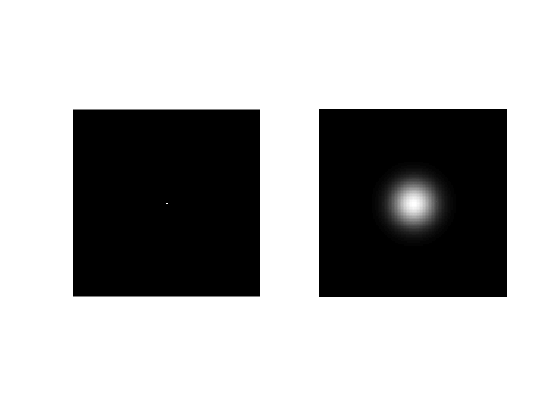


psf=gaussfft(img,t);
figure()
subplot(1,2,1)
showgrey(img)
subplot(1,2,2)
showgrey(psf)


Variance=variance(psf)

Variance =   100.0000    0.0000
    0.0000  100.0000


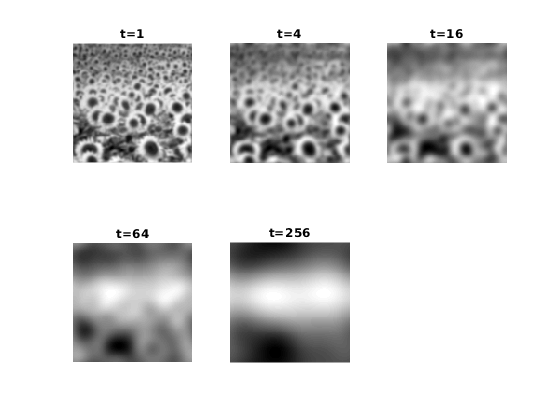



% Question 16
t1=[1,4,16,64,256];
img=sunflower128;
figure()
title('Convolution between image and discretized gaussian kernel with different variance')
for i=1:length(t1)
psf = gaussfft(img, t1(i));
subplot(2,3,i)
showgray(psf)
title(['t=',num2str(t1(i))])
    
end

Question 17, 18

disp('Question 17, 18')
office = office256;
add = gaussnoise(office, 16);
sap = sapnoise(office, 0.1, 255);
t=1;
wheight=3;
WWidth=3;
cutoff=0.18;
type='l';
office_n=sap;


figure()
subplot(2,2,1)
showgrey(office_n)
title('Image with noise')
subplot(2,2,2)
showgrey(gaussfft(office_n,t))
title(['Gaussian smoothing with t=',num2str(t)])
subplot(2,2,3)
showgrey(medfilt(office_n,wheight,WWidth))
title(['Median filtering [',num2str(wheight),',',num2str(WWidth),']'])
subplot(2,2,4)
showgrey(ideal(office_n,cutoff,type))
title(['Low pass filtering [',num2str(cutoff),',',num2str(type),']'])

Question 19, 20

disp('Question 19, 20')
cutoff=0.2;
t=1;
img = phonecalc256;
smoothimg = img;
smoothimg1 = img;
smoothimg2 = img;

N=5;
figure()
for i=1:N
if i>1
% generate subsampled versions
img = rawsubsample(img);
smoothimg1 = gaussfft(smoothimg1, t);
smoothimg2=ideal(smoothimg2,cutoff, 'l');
smoothimg1 = rawsubsample(smoothimg1);
smoothimg2=rawsubsample(smoothimg2);
end
subplot(3, N, i)
showgrey(img)
title(['Subsample ',num2str(i)])
subplot(3, N, i+N)
showgrey(smoothimg1)
title(['gaussian smoothing ',num2str(i)])
subplot(3, N, i+2*N)
showgrey(smoothimg2)
title(['low-pass smoothing ',num2str(i)])
end

